clf;
clear;

RGB = imread("../materials/PeppersRGB.tif");
size(RGB)

ans =    512   512     3


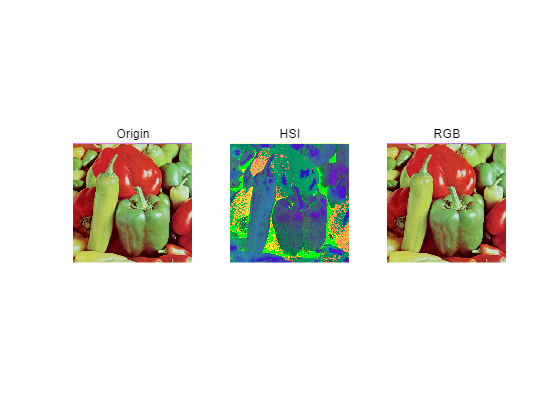


HSI = my_RGB2HSI(RGB);
RGB_new = my_HSI2RGB(HSI);
RGB_new = uint8(RGB_new);

subplot(1,3,1);
imshow(RGB,[]);title('Origin');
subplot(1,3,2);
imshow(HSI,[]);title('HSI');
subplot(1,3,3);
imshow(RGB_new,[]);title('RGB');

function HSI = my_RGB2HSI(RGB)
    RGB_double = im2double(RGB);
    [r, c, k] = size(RGB_double);
    HSI = zeros(r, c, k);
    
    for i = 1 : r
        for j = 1 : c
            R = RGB_double(i,j,1);
            G = RGB_double(i,j,2);
            B = RGB_double(i,j,3);
            theata = acos(0.5*((R-G)+(R-B)) / (sqrt((R-G)^2+(R-B)*(G-B))));

            if (B <= G)
                HSI(i,j,1) = theata;
            else
                HSI(i,j,1) = 2*pi-theata;    
            end 
            HSI(i,j,1) = HSI(i,j,1)/(2*pi);
            min_value = min(min(R,G),B);
            
            HSI(i,j,2) = 1 - (3/(R+G+B+eps))*min_value;
            HSI(i,j,3) = (R+G+B)/3;
        end
    end
end

function RGB = my_HSI2RGB(HSI)
    HSI = im2double(HSI);
    [r,c,k] = size(HSI);
    RGB = zeros(r,c,k);

    for i = 1 : r
        for j = 1 : c
            H = HSI(i,j,1)*2*pi;
            S = HSI(i,j,2);
            I = HSI(i,j,3);

            if (H>=0 && H<2/3*pi)
                RGB(i,j,1) = I*(1+S*cos(H)/(cos(pi/3-H)));
                RGB(i,j,3) = I*(1-S);
                RGB(i,j,2) = 3*I-(RGB(i,j,1)+RGB(i,j,3));
            elseif (H>=2/3*pi && H<4/3*pi)
                H = H-2*pi/3;
                RGB(i,j,1) = I*(1-S);
                RGB(i,j,2) = I*(1+S*cos(H)/(cos(pi/3-H)+eps));
                RGB(i,j,3) = 3*I-(RGB(i,j,1)+RGB(i,j,2));
            elseif (H>=4/3*pi && H<=2*pi)
                H = H-4*pi/3;
                RGB(i,j,2) = I*(1-S);
                RGB(i,j,3) = I*(1+S*cos(H)/(cos(pi/3-H)+eps));    
                RGB(i,j,1) = 3*I-(RGB(i,j,2)+RGB(i,j,3));
            end
        end
    end
    RGB = RGB*255;
end